clear

4-1

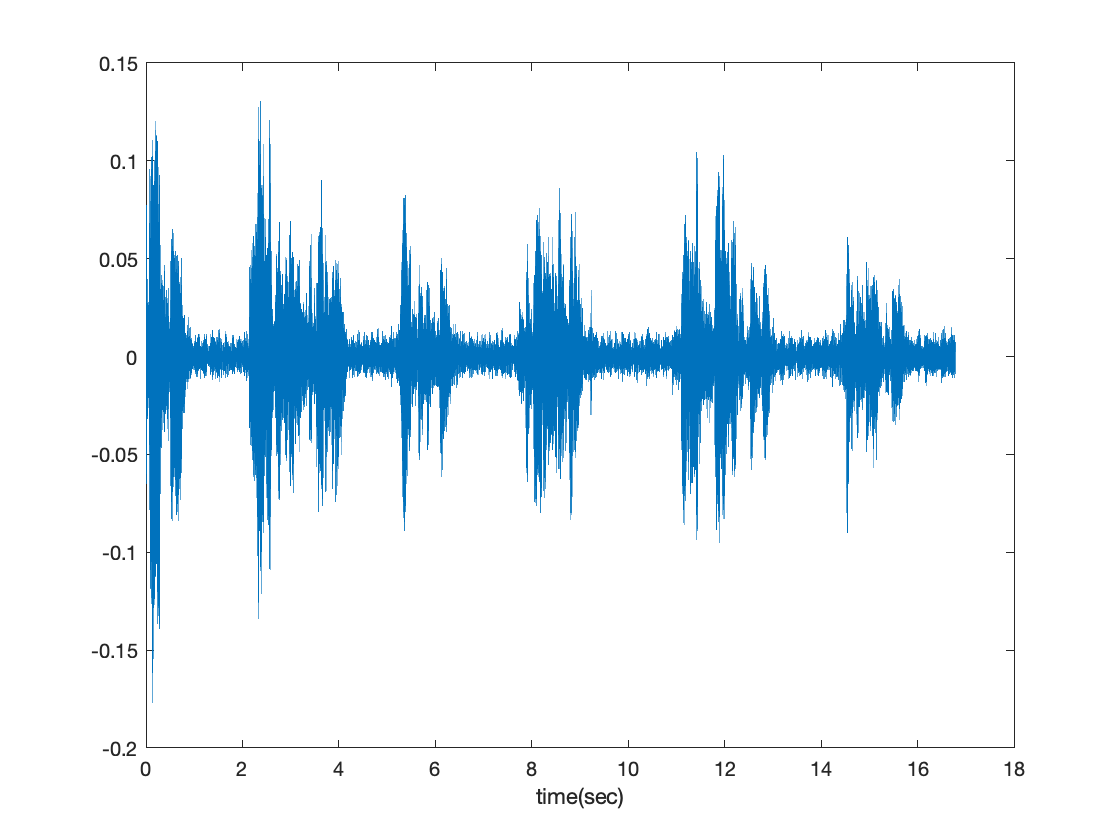

[x,Fs] = audioread("ebtehaj.wav");
t=0:1/(Fs):numel(x(:,1))/Fs;
t(end)=[];
plot(t,x(:,1))
xlabel("time(sec)")

audiowrite("x.wav",x,Fs)

4-3

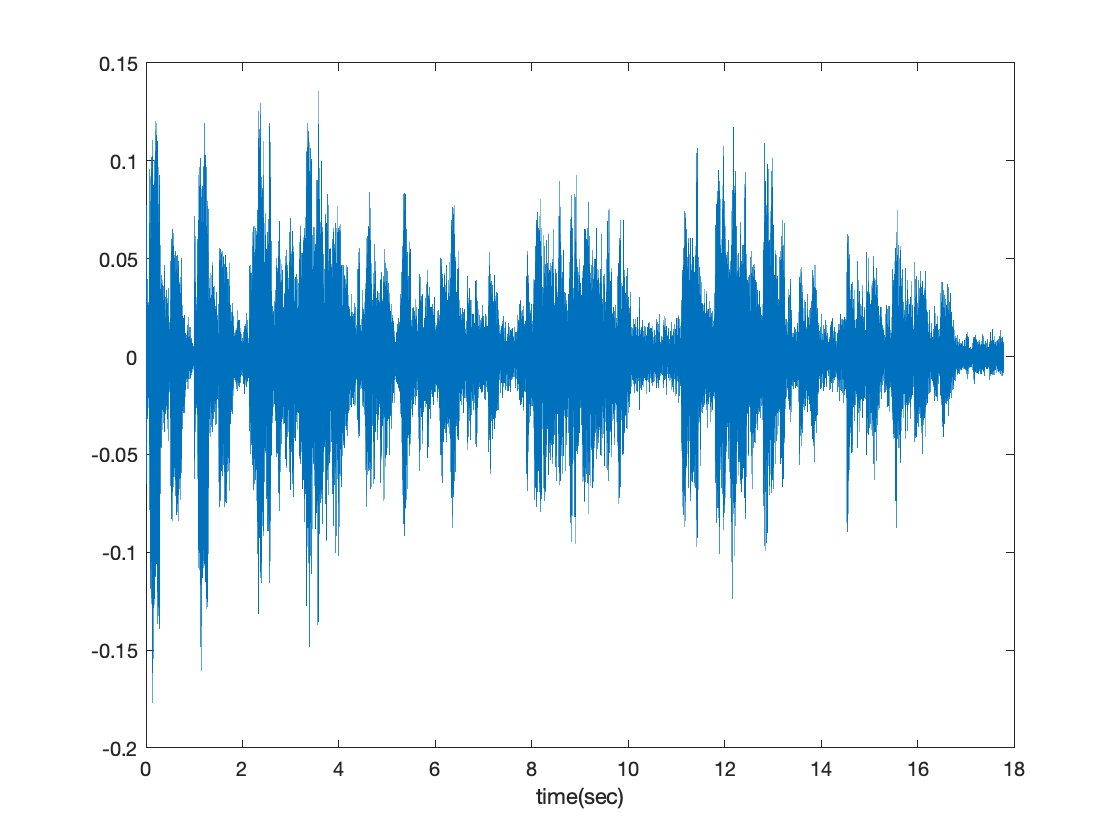

h=[1 zeros(1,44098) 0.9];
y=conv(x(:,1),h);
T=0:1/(44089.4):17.79;
plot(T,y)
xlabel("time(sec)")

fs=44089;
sound(y,fs)
audiowrite("y.wav",y,fs)

4-4

h1=[1 zeros(1,11000) 0.3]

h1 =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


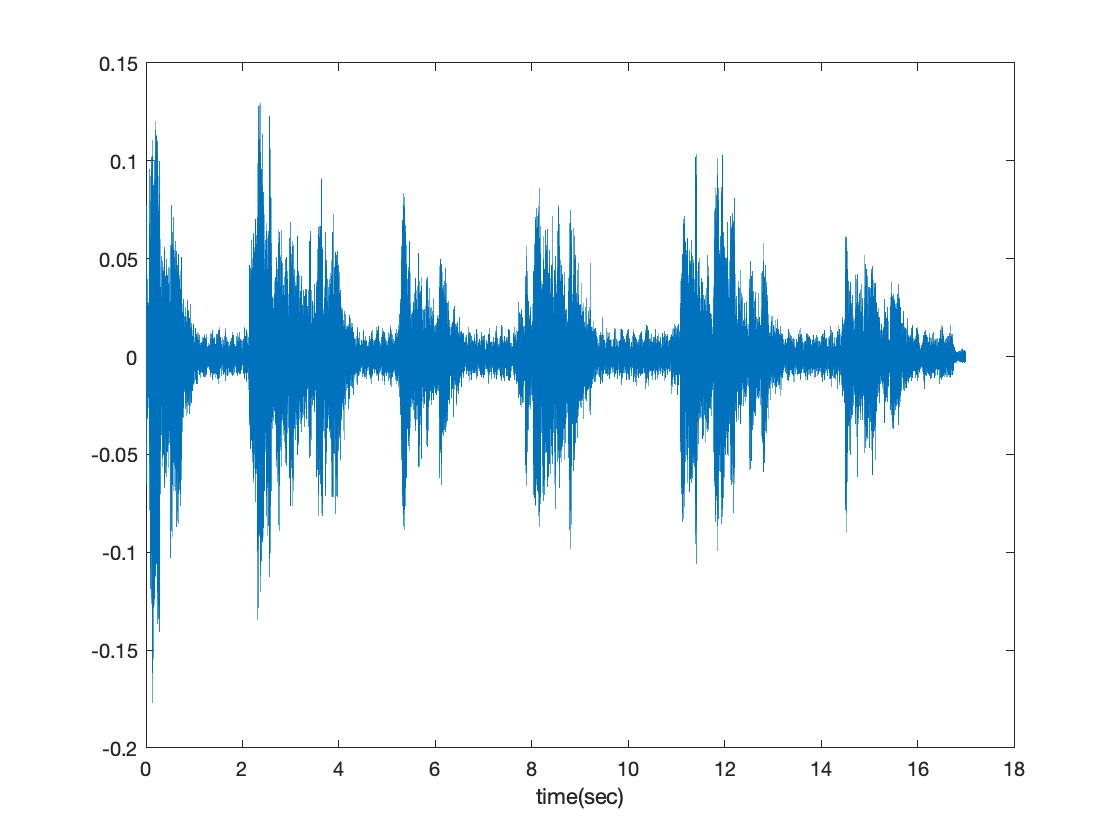

y1=conv(x(:,1),h1);
T1=0:1/(44191.35):17;
plot(T1,y1)
xlabel("time(sec)")

fs_=44191;
sound(y1,fs_)
audiowrite("y_best.wav",y1,fs_)

4-6

[x_test,Fs_test] = audioread("x_test.wav")

x_test =     0.0078
         0
         0
   -0.0078
   -0.0078
   -0.0156
   -0.0234
   -0.0156
   -0.0312
   -0.0312


Fs_test = 11025

sound(x_test,Fs_test)
[y_test,fs_test] = audioread("y_test.wav")

y_test =     0.0068
         0
         0
   -0.0068
   -0.0068
   -0.0136
   -0.0204
   -0.0136
   -0.0273
   -0.0273


fs_test = 11025

sound(y_test,fs_test)
[c,lags] = xcorr(x_test,y_test)

c = 	1.0e+03 *

   -0.0000
         0
   -0.0000
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


lags =       -94022      -94021      -94020      -94019      -94018      -94017      -94016      -94015      -94014      -94013      -94012      -94011      -94010      -94009      -94008      -94007      -94006      -94005      -94004      -94003      -94002      -94001      -94000      -93999      -93998      -93997      -93996      -93995      -93994      -93993      -93992      -93991      -93990      -93989      -93988      -93987      -93986      -93985      -93984      -93983      -93982      -93981      -93980      -93979      -93978      -93977      -93976      -93975      -93974      -93973


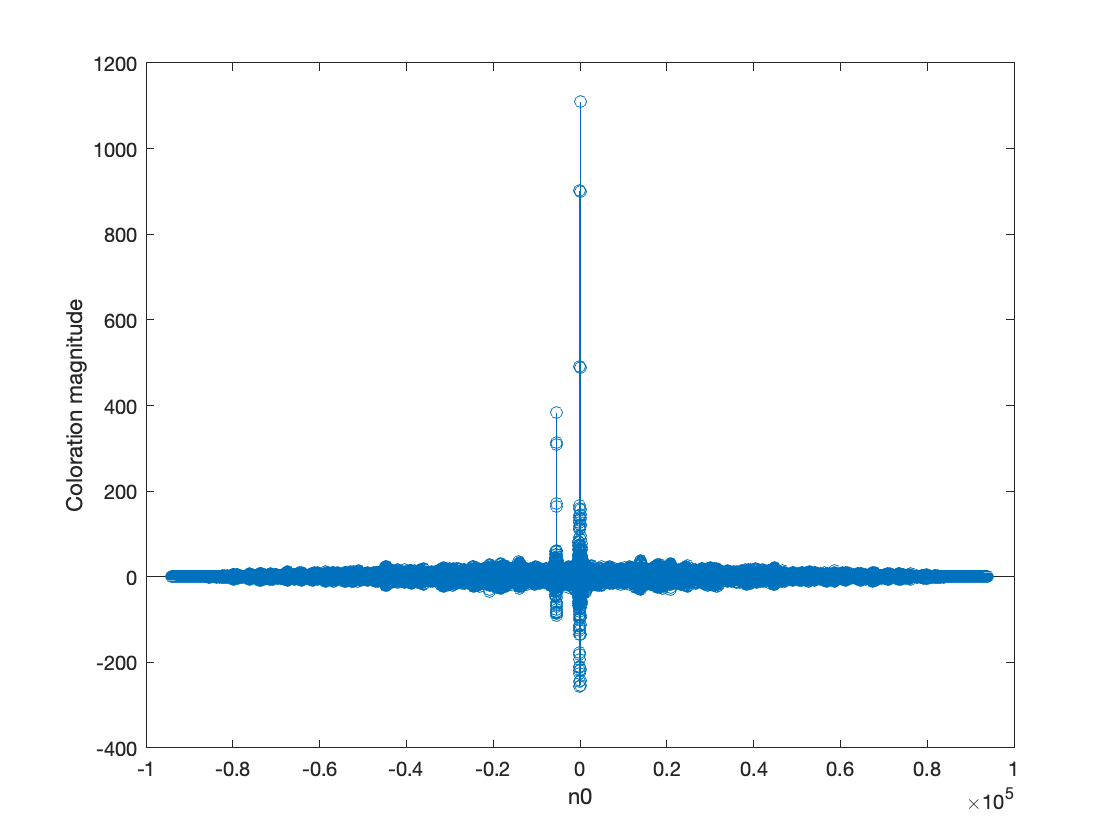

stem(lags,c)
xlabel('n0')
ylabel('Coloration magnitude')